# Part 7:  Hypothesis Testing

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

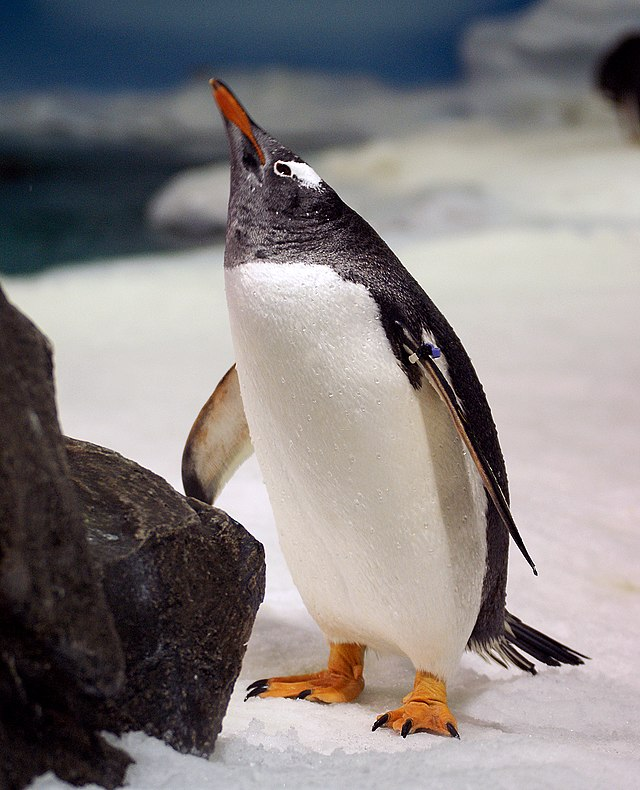

A Gentoo penguin looking towards the [skies](https://commons.wikimedia.org/wiki/File:Gentoo_Penguin._(9)_(8670581675).jpg). 

In this script, we'll explore how to test a hypothesis using MATLAB®! If you've ever heard someone referring to a "p-value", this section will explain what they mean.

Make sure you complete the other live scripts in this statistics curriculum module before starting here, but if you need to reload any variables, this block of code will add `penguins` to your workspace and clean it up: 

filename = "penguins.csv";
penguins = readtable(filename);
penguins.species = categorical(penguins.species);
penguins.island = categorical(penguins.island);
penguins.sex = categorical(penguins.sex);
penguins1 = rmmissing(penguins);
chinstrap = penguins1(penguins1.species == "Chinstrap",:);
gentoo = penguins1(penguins1.species == "Gentoo",:); 
adelie = penguins1(penguins1.species == "Adelie",:);

## Develop null and alternate hypotheses

Let's assume that you collected all this penguin data, and before analyzing it, you came up with a few hypotheses about how penguin species differ. Now you'd like to know if they are supported by the dataset! Several different statistical tests can be used to test a hypothesis. We'll look at a couple of common ones here.

We will consider and test hypotheses one at a time.

***Hypothesis 1: Male penguins have significantly higher body mass than female penguins. ***

Because we want to easily compare males and females, let's quickly get organized. Much as we did with separating by species, we make a table for males and a table for females: 

male = penguins1(penguins1.sex == "MALE",:);

  Fill in the blank to create the female table, then uncomment the line and run this section: 

%female = penguins1(  == "FEMALE",:);

In [hypothesis testing](https://en.wikipedia.org/wiki/Statistical_hypothesis_testing), we always rewrite our initial hypothesis into a [**null**](https://en.wikipedia.org/wiki/Null_hypothesis) and [**alternate**](https://en.wikipedia.org/wiki/Alternative_hypothesis) hypothesis. Your initial hypothesis is the alternate hypothesis, which in this case is that males have a significantly higher body mass than females.  The null always predicts no effect or relationship between the variables you are looking at. In this case, it would say that there is *no difference in the weights of male and female penguins. *If we want to say the male and female weights are significantly different, we have to prove the null hypothesis is wrong (or 'reject' it). 

We need to compare two groups of different sizes and we'd like to determine if their means are significantly different from one another. To do this, we will use an unpaired, [two-sample t-test](https://www.mathworks.com/help/stats/ttest2.html). A t-test compares the averages of different groups and determines if these groups are "statistically" different or if it's possible for the differences in groups to arise based on random chance. The null hypothesis is always that the differences have arisen from random chance. The t-test returns a value of 1 if the null hypothesis is rejected (this is referred to as a test decision, h). If the null hypothesis is true (there is no relationship), the value of h is 0. 

The null hypothesis will be accepted (h=0) if the probability that the data in your two groups are drawn from one big group (meaning the difference between groups is random chance) is greater than some given significance threshold. In biology, this threshold is often 5% probability, and this is the default significance level used in the built-in MATLAB functions we will use here. However, this varies based on discipline. 

## Visualize your hypotheses using a box plot 

Let's visualize our penguins' weight again for a second, returning to the box plot we learned earlier : 

boxplot(penguins1.body_mass_g, penguins1.sex) % plot body mass, broken up by sex 
xlabel("Sex")
ylabel("Body Mass (g)")

These distributions look different. If you picked a female weight at random, there is some chance that it would overlap with the male weight distribution. But if these two weight distributions looked the same (no skew or offset between them), then there would be a close to 100% chance that if you picked a female weight at random, this would overlap with the male weight distribution. If that were the case, the male and female distributions could be considered one distribution or population. The t-test calculates how likely it is that the two distributions you are comparing are from one indistinguishable distribution or population (you can also imagine this as two histograms for each population that overlap completely). In our case, if the likelihood of your data being from one indistinguishable group is greater than 5%, the null hypothesis is accepted. And we can say that the alternate hypothesis, the hypothesis we start by defining, is correct if there is a greater than 95% chance that the two data distributions are different and not completely overlapping. 

This 'likelihood' is called the p-value. We represent 5% in decimal format as 0.05, so a p-value of less than 0.05 rejects the null hypothesis, and any p-value greater than 0.05 accepts it.  This threshold of 0.05 is commonly used in biology but varies by discipline, and you can choose your significance level. Some people use 0.005 which means there is a 99.5% chance that the data come from different distributions. Whatever significance level you choose, you have to choose it before you run any tests.  How much lower the p-value is than the significance threshold gives us a sense of how significantly different the two populations are. Anytime the p-value falls below the significance threshold, we consider the result 'statistically significant'.

## Run a hypothesis test 

Let's try this out! As always, MATLAB has some easy built-in functions for hypothesis testing. In the case of the two-sample t-test we will use [`ttest2()`](https://www.mathworks.com/help/stats/ttest2.html)`.`

`ttest2()` takes as input the two populations we are comparing, and gives h (the test decision), and p (the p-value) as output: 

[h, p] = ttest2(male.body_mass_g, female.body_mass_g)

In this case, h is 1, so the null hypothesis is rejected. This is because the p-value is well below 0.05 (the significance level). Therefore, we can say that the weight differences between male and female penguins are statistically significant. 

Often, you want to pair the p-value with a graphical representation of the hypothesis. A chart like the box plot is often used for this. From that plot, it is clear that the males have a higher body mass on average than the females, and we just proved that this difference is statistically significant. Therefore, the hypothesis is correct. This is the type of analysis you might see in a scientific paper. 

## Give it a try!

Let's work with another hypothesis. ***Hypothesis 2: Males have significantly longer bills than females. ***

 Given this hypothesis, consider what the null and alternate hypotheses are and jot them down. 

  Then, uncomment this line and fill in the blank to test the hypothesis: 

%[h,p] = ttest2( ,female.bill_length_mm)

  Finally, create a box plot of bill length broken up by sex by filling in the blank, uncommenting this line of code, and running the section: 

%boxplot( , penguins1.sex)
xlabel ("Sex")
ylabel ("Bill Length(mm)")

 Is your hypothesis proven or disproven (is the test decision, h, 0, or 1) What does the p-value tell you?

###  Exercise: Test the hypothesis that Chinstrap penguins are larger than Adelie penguins.

Consider a new hypothesis. ***Hypothesis 3: Chinstrap penguins are significantly larger than Adelie penguins. ***

What are the null and alternate hypotheses here? 

**A:** Use` ttest2()` to test this hypothesis (hint: you'll need to use the individual species tables, e.g. `chinstrap.body_mass_g`). Use` [h, p]` as the output so you return both the test decision and the p-value. 

 Is your hypothesis proven or disproven? 

**B:** Create a box plot showing body mass broken up by species (Hint: you can just plot all 3 species! Use `penguins1.species). `

**C:** Add an x and y label to your box plot: 

In this case, the test decision h, is 0, meaning the null hypothesis is accepted. We can see that this is because the p-value is equal to 0.67, which is much greater than 0.05. The hypothesis is therefore rejected-- Chinstrap penguins and Adelie penguins do not significantly differ in body mass! 

From the box plot, it seems pretty clear that it is hard to distinguish the body mass of Adelie and Chinstrap penguins, but Gentoo penguins are much bigger, as we discussed earlier!

  For the t-test and box plot above, try instead comparing Gentoo and Adelie penguins. Is the difference statistically significant in this case?

You may also use a paired, one-sample t-test (MATLAB: [**ttest()**](https://www.mathworks.com/help/stats/ttest.html)) if comparing within a single population. Imagine you measured a group of penguins and then came back one year later and measured the same penguins. If you wanted to test whether their weights had changed significantly, you would compare the weight of each penguin on the first visit to its own weight on the second visit! 

To explore more types of hypothesis tests in MATLAB, click [here](https://www.mathworks.com/help/stats/available-hypothesis-tests.html). 

In sum, this module explored using MATLAB for descriptive statistics, predictive modeling, correlations, and hypothesis testing. 

## Further resources

To learn more about statistics in MATLAB, try the self-paced [Introduction to Statistical Methods with MATLAB course](https://matlabacademy.mathworks.com/details/introduction-to-statistical-methods-with-matlab/stats)-- this is a great resource!

Work on the problem set at the bottom of this module to further practice some concepts presented in this module. 

## Exercise answer:

% For the give it a try section, 
% [h, p] = ttest2(male.bill_length_mm, female.bill_length_mm) % t-test
% boxplot(penguins1.bill_length_mm, penguins1.sex) % box plot

%Exercise:

[h,p] = ttest2(chinstrap.body_mass_g, adelie.body_mass_g) % A 
boxplot(penguins1.body_mass_g, penguins1.species) % B
xlabel ("Species") % C
ylabel ("Body Mass (g)")

[*Continue to next section (Problem set)*](matlab: edit S8_Problem_Set.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)